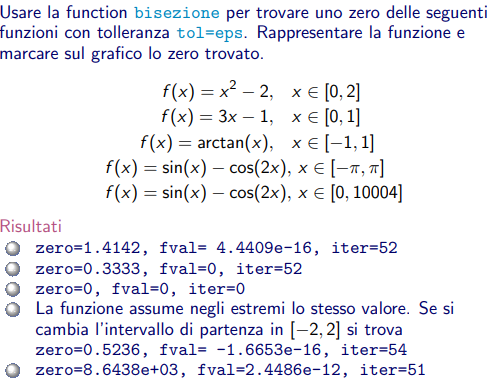

clear all
close all
f = @(x) x^2-2; a=0;b=2;
%f = @(x) 3*x-1;a=0;b=1;
%f = @(x) atan(x);a=-1;b=1;
%f = @(x) sin(x)-cos(2*x);a=-pi;b=pi;
%f = @(x) sin(x)-cos(2*x);a=-2;b=2;
%f = @(x) sin(x)-cos(2*x);a=0;b=10004;
[zero fval iter] = bisezione(f,a,b,eps)

zero = 1.4142

fval = 4.4409e-16

iter = 52

fplot(f,[a b])

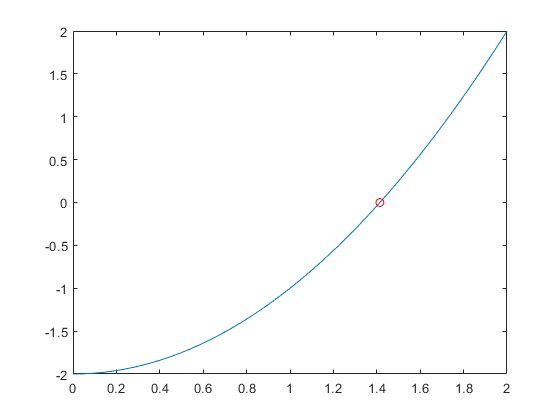

hold on
plot(zero,fval,'or')

legend('funciton','zero_1')

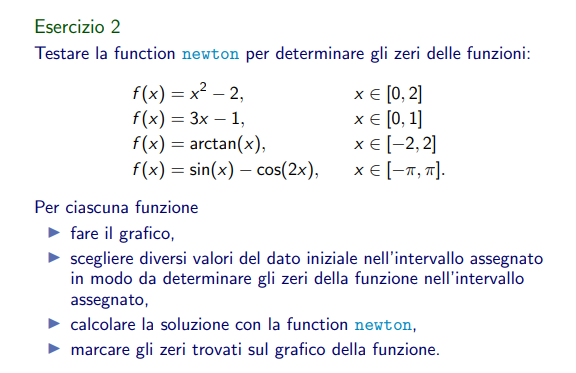

clear all
close all
% ATTENZIONE !!!!
% syms serve per fare la derivata delal funzione all'interno di newon
syms x
f = x^2-2; a=0;b=2;
%f = 3*x-1;a=0;b=1;
%f = atan(x);a=-1;b=1;
%f = sin(x)-cos(2*x);a=-pi;b=pi;
x0 = 1.8;
[zero,fz,iter,xk] = newton(f,x0,eps,100);

zero = 1.4142

fz = -4.4409e-16

iter = 5

xk =     1.8000    1.4556    1.4148    1.4142    1.4142    1.4142


fplot(f,[a b])
hold on
plot(zero,fz,'or')

legend('funciton','zero_1')

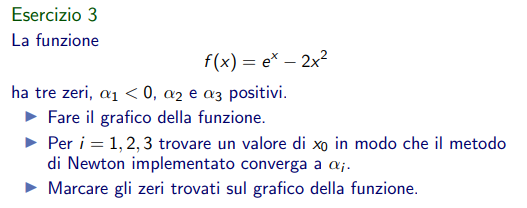

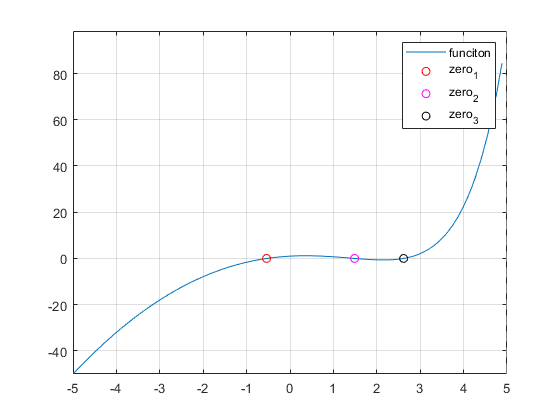

clear all
close all
% ATTENZIONE !!!!
% syms serve per fare la derivata delal funzione all'interno di newon
syms x
f = exp(x)-2*x^2;
x0 = -5;
[zero,fz,iter,xk] = newton(f,x0,eps,100);
fplot(f)
grid on
hold on
plot(zero,fz,'or')

x0 = 1;
[zero,fz,iter,xk] = newton(f,x0,eps,100);
hold on
plot(zero,fz,'om')

x0 = 3;
[zero,fz,iter,xk] = newton(f,x0,eps,100);
hold on
plot(zero,fz,'ok')
legend('funciton','zero_1','zero_2','zero_3')

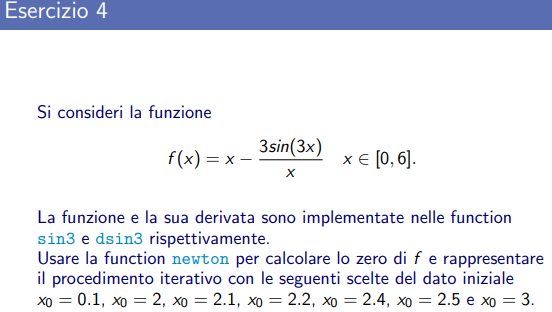

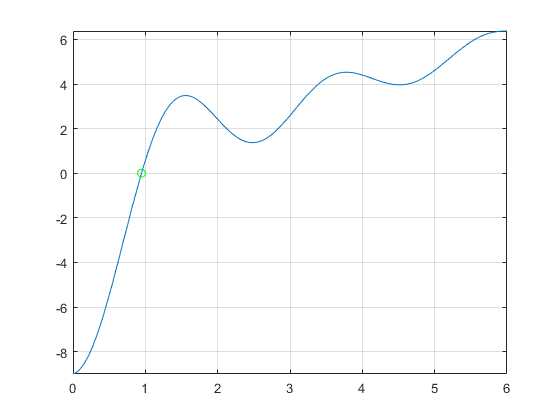

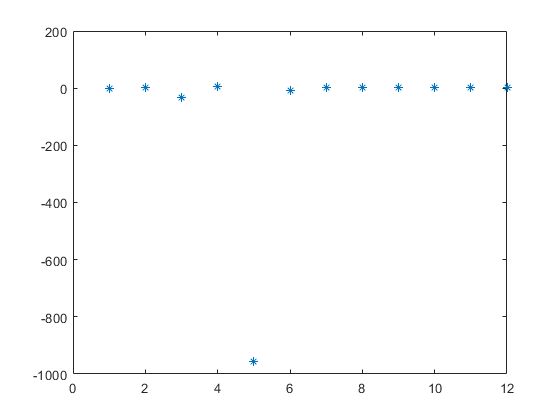

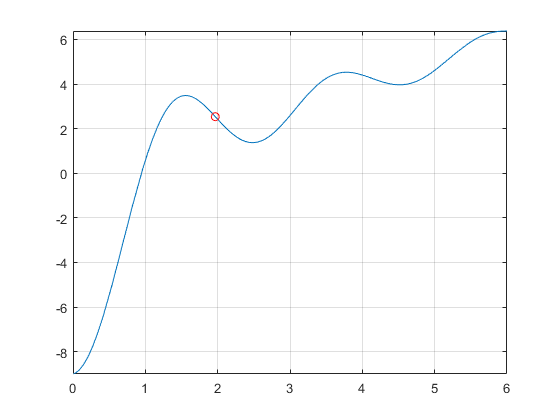

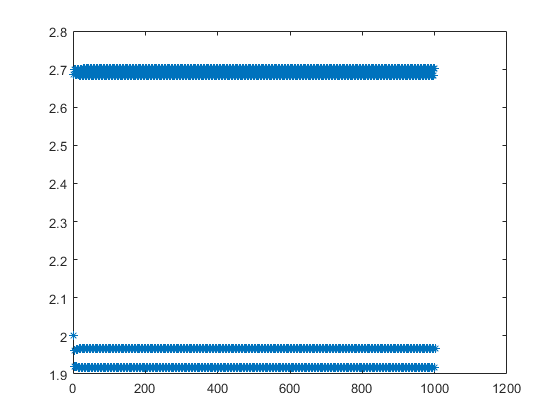

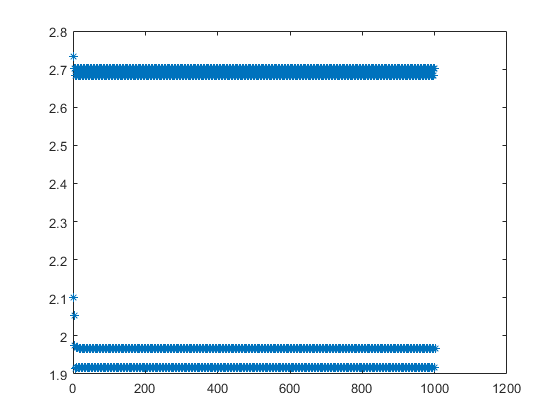

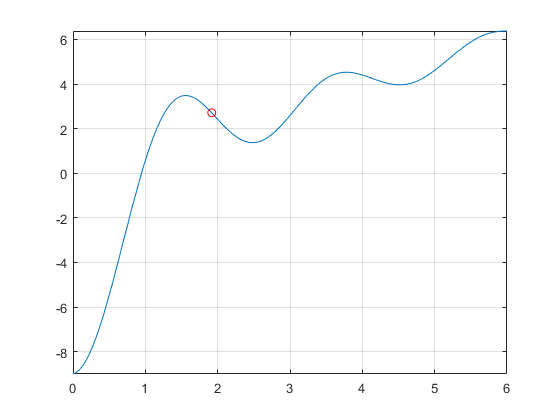

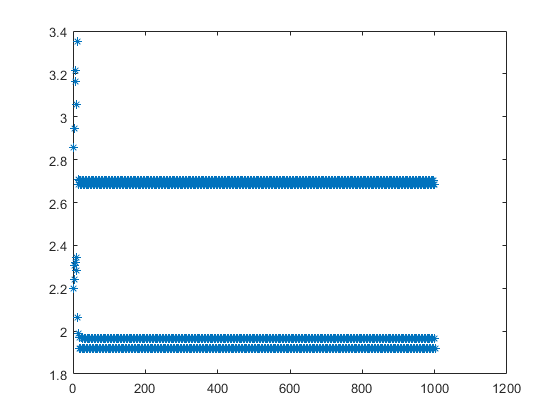

clear all
close all
% ATTENZIONE !!!!
% syms serve per fare la derivata delal funzione all'interno di newon
syms x
f = x-(3*sin(3*x))./(x);
X0 =[0.1 2 2.1 2.2 2.4 3];
figure()
fplot(f,[0 6])
grid on
hold on
for x0 = X0
    [zero,fz,iter,xk] = newton(f,x0,eps,1000);
    if(fz < 0.1 && fz > -0.1)
        color = "g";
    else
        color = "r";
    end
    if zero >= 0
        plot(zero,fz,"o"+color)
    end
end

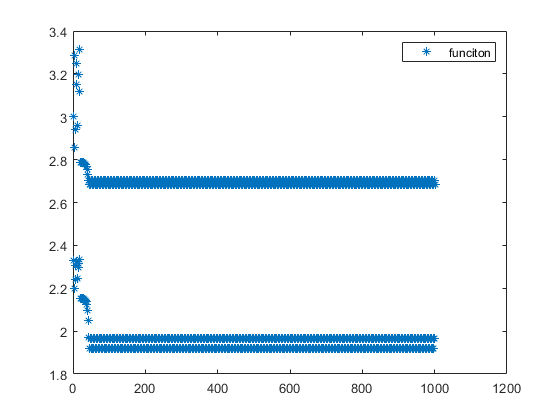

legend('funciton','zero giusto','zero errato')

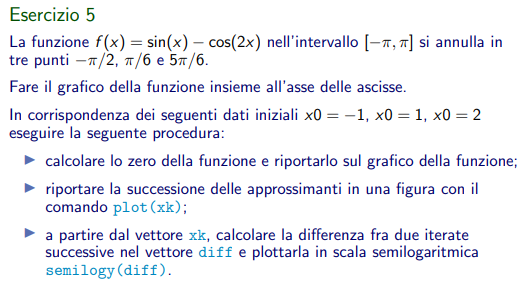

x0 = -1


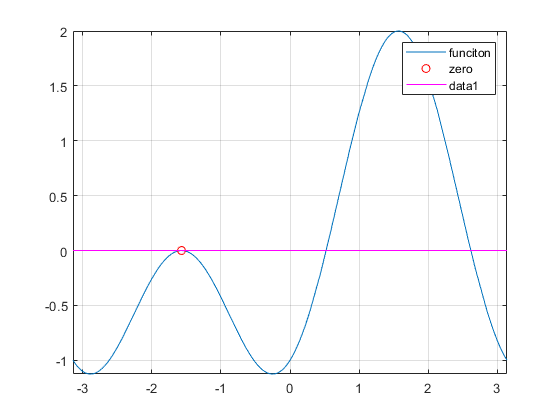

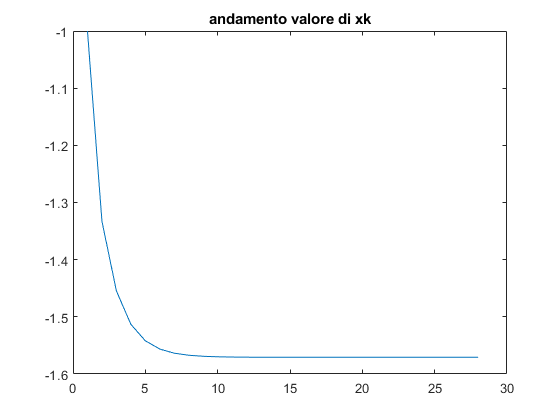

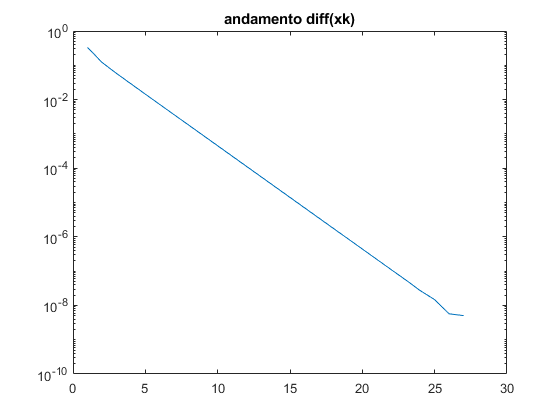

x0 = 1


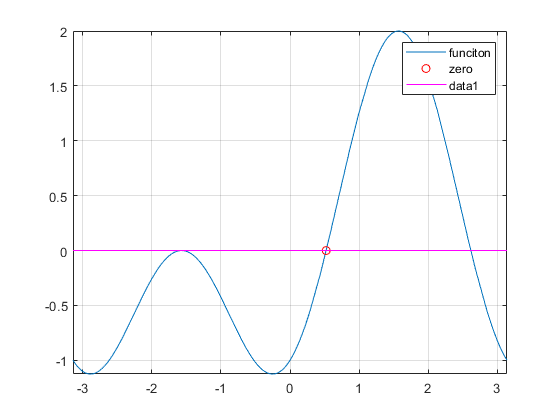

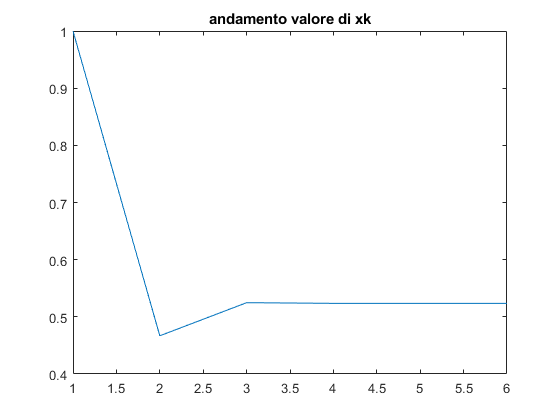

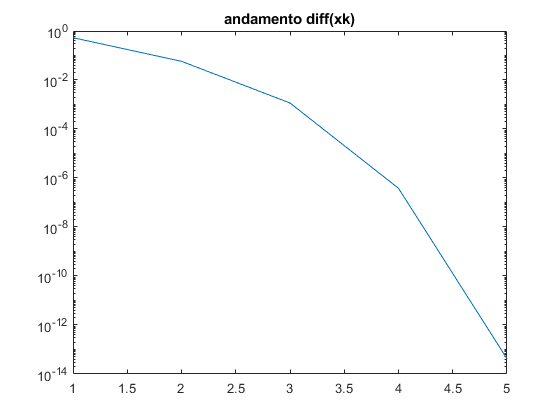

x0 = 2


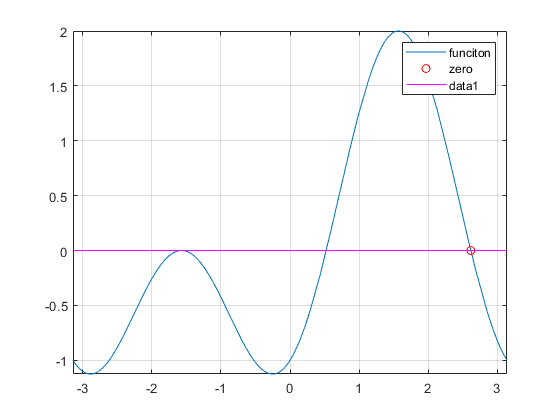

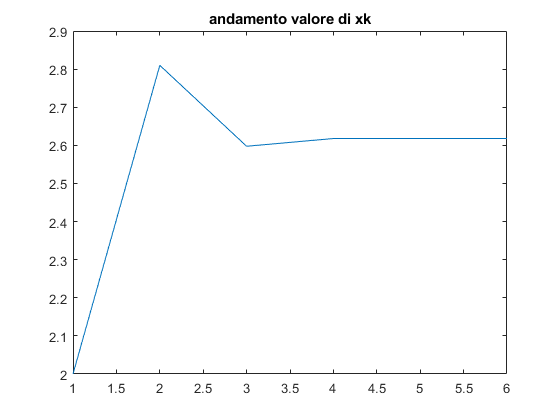

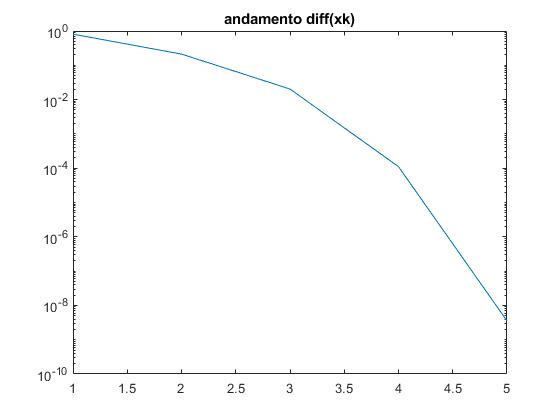

clear all
close all
% ATTENZIONE !!!!
% syms serve per fare la derivata delal funzione all'interno di newon
syms x
f = sin(x)-cos(2*x);
X0 =[-1 1 2];
for x0 = X0
    disp("x0 = " + x0)
    figure()
    fplot(f,[-pi pi])
    
    grid on
    hold on
    [zero,fz,iter,xk] = newton(f,x0,eps,100);
    plot(zero,fz,"or")
    legend('funciton','zero')
    plot([-pi pi],[0 0],'m')
    hold off
    figure()
    plot(xk)
    title("andamento valore di xk")
    
    diff=abs(xk(1:end-1)-xk(2:end));
    figure()
    semilogy(diff)
    title("andamento diff(xk)")
end

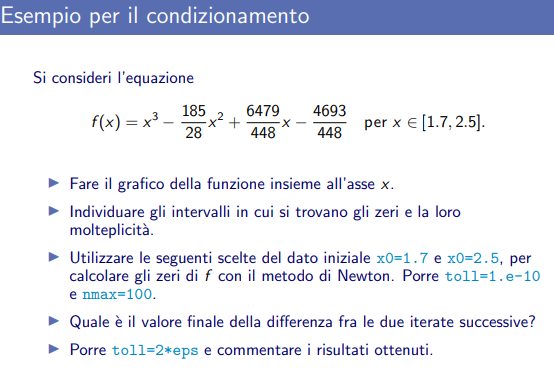

clear all
close all
syms x;
f = x^3-185/28*x^2+6479/448*x-4693/448;
fplot(f,[1.7 2.5])
hold on
plot([1.7 2.5],[0 0])
[zero,fz,iter,xk] = newton(f,1.7,1.e-10,100);
differenza=abs(xk(end)-xk(end-1))

differenza = 1.6426e-07

plot(zero,fz,'or')
[zero,fz,iter,xk] = newton(f,2.2,1.e-10,100);
differenza=abs(xk(end)-xk(end-1))

differenza = 3.5848e-08

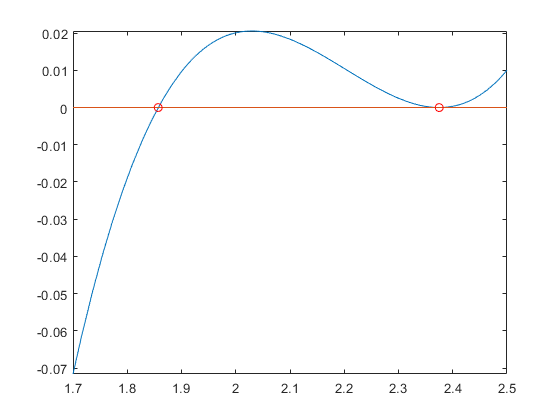

plot(zero,fz,'or')

[ris,fz,iter,xk]=newton(f,1.7,2*eps,100);
differenza=abs(xk(end)-xk(end-1))

differenza = 1.3323e-14

[ris,fz,iter,xk]=newton(f,2.2,2*eps,100);
differenza=abs(xk(end)-xk(end-1))

differenza = 3.5848e-08

[ris,fz,exitflag,output]=fzero(matlabFunction(f),[1.7 2.5],optimset('Display','iter'));

 
 Func-count    x          f(x)             Procedure
    2             2.5     0.0100446        initial
    3         2.40157   0.000384489        interpolation
    4         2.39768   0.000277999        interpolation
    5         2.38755    8.3486e-05        interpolation
    6         2.04377     0.0204754        bisection
    7         1.87189    0.00373196        bisection
    8         1.87189    0.00373196        interpolation
    9          1.8581   0.000255883        interpolation
   10         1.85714  -1.66749e-06        interpolation
   11         1.85714   6.18446e-09        interpolation
   12         1.85714   1.47438e-13        interpolation
   13         1.85714  -1.77636e-15        interpolation
   14         1.85714  -3.55271e-15        interpolation
   15         1.85714  -3.55271e-15        bisection
   16         1.85714  -3.55271e-15        interpolation
   17         1.85714   1.77636e-15        interpolation
   18         1.85714             0        interpol